# Introducing ISET3d calculations

Renders a scene containing a sphere to illustrate the basic read, edit, write cycle.

**See also:**

    t_piIntro_*, piRecipeDefault, @recipe

## Initialize ISET and Docker

Start up ISET and check that docker is configured 

ieInit;
if ~piDockerExists, piDockerConfig; end

## Read the recipe

thisR = piRecipeDefault('scene name','sphere');

thisR.set('light','all','delete');

The recipe has many fields that control the scene properties how it is rendered.  We simply list them here.  A lot of this wiki describes how to set and get properties from the many slots ISET3d recipe slots.

## Edit the recipe

For example, we can place a point light in the sphere scene.  Without a light, the scene will appear black!

thisLight = piLightCreate('point','type','point','cameracoordinate', true);
thisR.set('light',thisLight, 'add');
thisR.set('light',thisLight.name,'specscale',0.5);
thisR.set('light',thisLight.name,'spd',[0.5 0.4 0.2]);

We can also set rendering properties.

thisR.set('film resolution',[192 192]);
thisR.set('rays per pixel',128);
thisR.set('n bounces',1); % Number of bounces

## Write the recipe, render it, and show it

piWrite(thisR);

In this example, we use a pinhole camera, so that we are effectively rendering the scene radiance.  If we include a lens, we would be rendering an optical image.

scene = piRender(thisR);

[INFO]: Render Locally.
[ERROR]: Runing Command: docker  --context remote-orange run -d -it  --gpus device=0  --name pbrt-gpu-wandell15191  -v /home/wandell/ISETRemoteRender:/home/wandell/ISETRemoteRender -v /acorn/data/iset/PBRTResources:/acorn/data/iset/PBRTResources  digitalprodev/pbrt-v4-gpu-ampere-ti bash 


Error using isetdocker/startPBRT (line 325)
[ERROR]:Failed to start Docker container: fbb4821949dd8b743d65274c4739c91efceed73476737d26d64d82bf5d5b6ac9
docker: Error response from daemon: failed to create task for container: failed to create shim task: OCI runtime create failed: runc create failed: unable to start container process: error during container init: error running prestart hook #0: exit status 1, stdout: , stderr: Auto-detected mode as 'legacy'
nvidia-container-cli: initialization error: nvml error: driver/library version mismatch: unknown

Run 'docker run --help' for more information


Error in 

sceneWindow(scene);

% dockerWrapper.getPrefs;
[scene, result] = piRender(thisR);

[INFO]: Render Locally.
[ERROR]: Runing Command: docker  --context remote-orange run -d -it  --gpus device=0  --name pbrt-gpu-wandell2003  -v /home/wandell/ISETRemoteRender:/home/wandell/ISETRemoteRender -v /acorn/data/iset/PBRTResources:/acorn/data/iset/PBRTResources  digitalprodev/pbrt-v4-gpu-ampere-ti bash 


Error using isetdocker/startPBRT (line 325)
[ERROR]:Failed to start Docker container: 102c09af71c22c5e97eb7b8a47ccbabef18ce18642720c4536e6f67bf3e5c604
docker: Error response from daemon: failed to create task for container: failed to create shim task: OCI runtime create failed: runc create failed: unable to start container process: error during container init: error running prestart hook #0: exit status 1, stdout: , stderr: Auto-detected mode as 'legacy'
nvidia-container-cli: initialization error: nvml error: driver/library version mismatch: unknown

Run 'docker run --help' for more information


Error in 

sceneWindow(scene);

## By default, piRender computes the scene or oi depth map

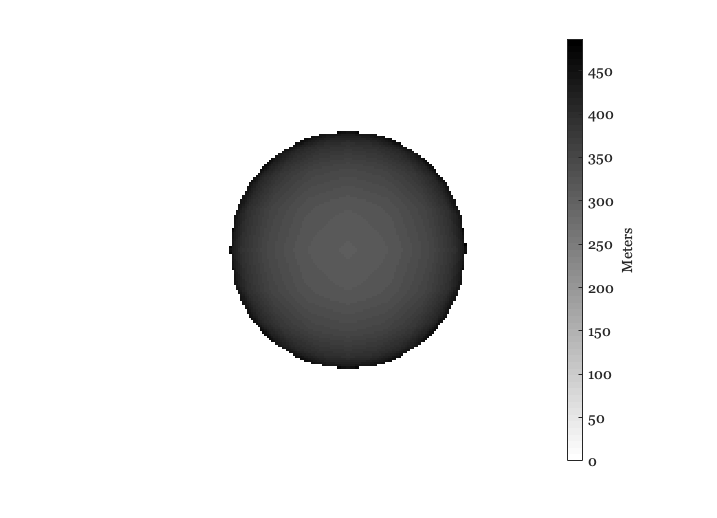

scenePlot(scene,'depth map');

## Change the light to a bluish light

You can edit the lights this way, adding a light which is more blue and distant 

% Remove the light we added
thisR.set('light',thisLight.name, 'delete');

% Create a new version with a different color temperature
thisLight = piLightCreate('distant','type','distant',  'spd', 9000,  'cameracoordinate', true);

thisR.set('light',thisLight, 'add');

This is an efficient way to Write, Render and Show without the separate calls.

[INFO]: Uploading data:
[INFO]: Sent 1175 bytes  received 380 bytes  3110.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-wandell468 sh -c " pbrt  --outfile /home/wandell/ISETRemoteRender/sphere/renderings/sphere.exr /home/wandell/ISETRemoteRender/sphere/sphere.pbrt "
[INFO]: Rendered remotely in: 2.23 sec
[INFO]: Downloading data:
[INFO]: Sent 488 bytes  received 225047 bytes  150356.67 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/sphere.exr


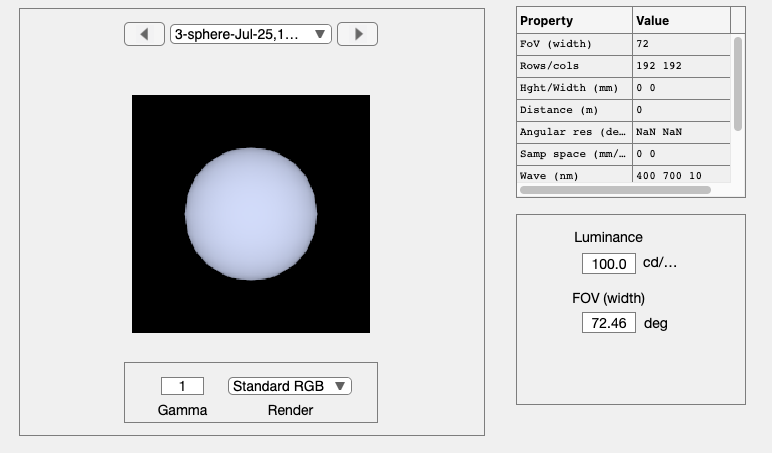

piWRS(thisR);

## Read an  FBX file and write it as PBRT

% FBX is converted into PBRT
fname = fullfile(piRootPath,'data','scenes','teapot-set','TeaTime-converted.pbrt');
 
thisR  = piRead(fname);

Error using piRead (line 122)
The value of 'fname' is invalid. It must satisfy the function: @(x)(exist(fname,'file')).

Convert scene unit from centimeter to meter

thisR.set('film resolution',[600 600]/2);
thisR.set('rays per pixel',32);

Set the render type.

One type is radiance, and here are the others

**rTypes = {'radiance','depth','both','all','coordinates','material','instance', 'illuminant','illuminantonly'};**

thisR.set('film render type',{'radiance','depth'});

%% move object
thisR.set('asset','Cylinder.001_B','world translation',[0.2 0 0]);

thisR.show('objects');

## Add a light

[INFO]: Uploading data:
[INFO]: Sent 1177 bytes  received 380 bytes  3114.00 bytes/sec
[INFO]: Data uploaded successfully.
[INFO]: USE Docker: docker  --context remote-orange exec -it  pbrt-cpu-wandell468 sh -c " pbrt  --outfile /home/wandell/ISETRemoteRender/sphere/renderings/sphere.exr /home/wandell/ISETRemoteRender/sphere/sphere.pbrt "
[INFO]: Rendered remotely in: 2.22 sec
[INFO]: Downloading data:
[INFO]: Sent 2012 bytes  received 85376 bytes  174776.00 bytes/sec
[INFO]: Data downloaded successfully.
[INFO]: Output file:  renderings/sphere.exr


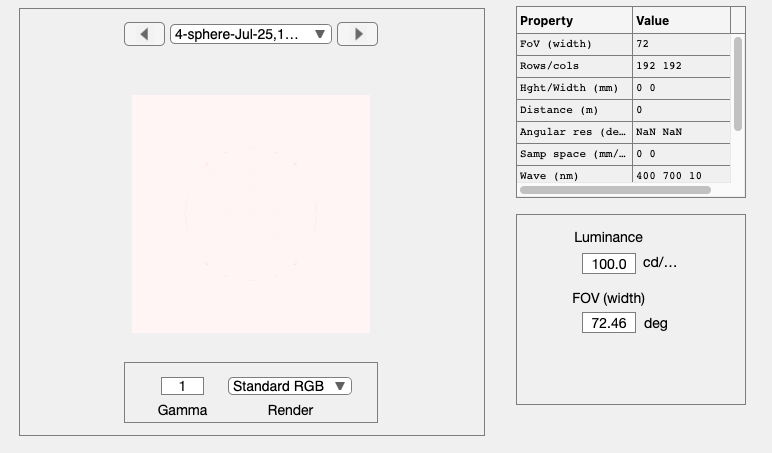

thisR.set('lights','all','delete');
lightName = 'new light';
newLight = piLightCreate(lightName,...
                        'type','infinite',...
                        'spd',[0.4 0.3 0.3],...
                        'specscale',1);
thisR.set('light', newLight, 'add');

% Render and return the scene
scene = piWRS(thisR);

Show the geometry

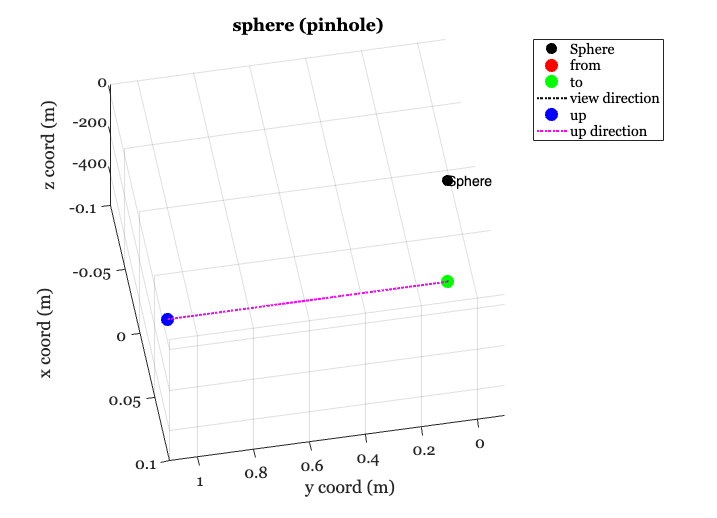

piAssetGeometry(thisR);view(-80,-65);